# Probability Theory in Matlab

The purpose of this document is to use the **Matlab** environment to generate random variables. Make sure you've read Chapter 2 first and then check this document before doing the homework.

## Generating Random numbers and plotting them

There are multiple functions to generate random numbers in Matalb. The two main ones are *rand() *and *randn()*. The first draws random numbers from a uniform distribution from (0, 1) and the second one draws random numbers from a normal distribution with 0 mean and standard deviation of 1. To create an array of random variables you can pass the size of the array as arguments of the function.

% Uniform distribution
u_dis = rand(3000, 1);
u_mean = mean(u_dis)

u_mean = 0.4934


% Normal distribution
n_dis = randn(3000, 1);
n_mean = mean(n_dis)

n_mean = 0.0141

n_std = std(n_dis)

n_std = 1.0005

You can use histograms to present the data

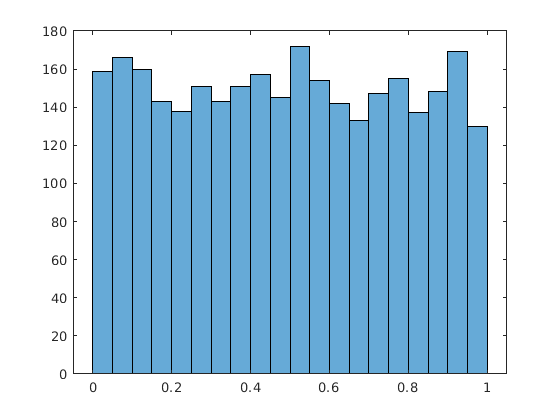

figure
histogram(u_dis)

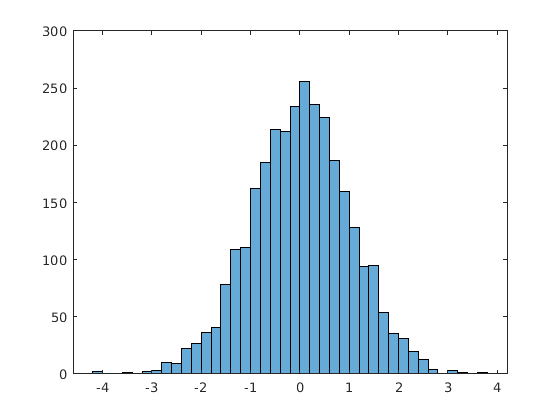


figure
histogram(n_dis)

From these basic distributions, and using what you've learned in Chapter 2, you can create normal distributions with a specific mean and standard deviation:

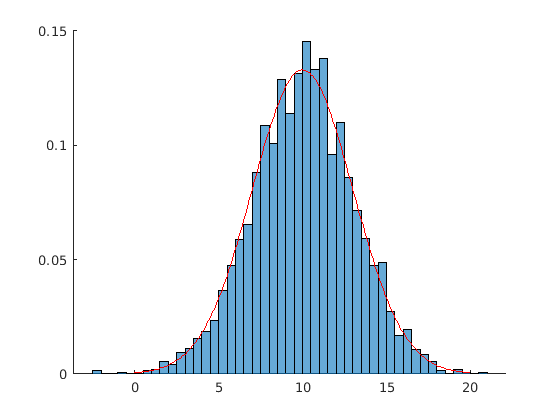

my_dis_mean = 10;
my_dis_std = 3;

my_dis = my_dis_std * n_dis + my_dis_mean;

x = 0:0.1:20;
% Norma
pdf = exp(-(x-my_dis_mean).^2./(2*my_dis_std^2))./(my_dis_std*sqrt(2*pi));

figure
hold on
% Here, the data are normalized to give an estimate of the distribution's
% pdf
histogram(my_dis,'Normalization','pdf')
plot(x, pdf, 'r')
hold off

## Simulating correlated noise

Section 2.7 shows how we can generate correlated noise. Here we will show an example of how we would create a 2 element random vector with zero mean and the desired covariance:

% Generate uncorrelated random vector and initialize correlated
x_unc = randn(2, 3000);
x_cor = zeros(size(x_unc));

% Covariance matrix
Q = [1, 0.5; 0.5, 1];

% Get eigenvalues(D) and eigenvectors(V)
[V, D] = eig(Q)

V =    -0.7071    0.7071
    0.7071    0.7071


D =     0.5000         0
         0    1.5000


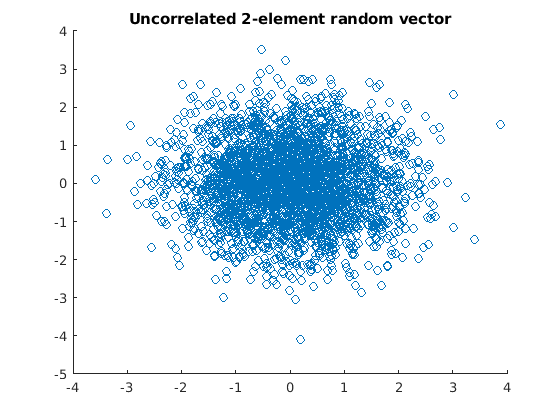


for i = 1 : length(x_unc)
    x_cor(:, i) = V * D * x_unc(:, i);
end

figure
scatter(x_unc(1,:), x_unc(2,:))
title('Uncorrelated 2-element random vector')

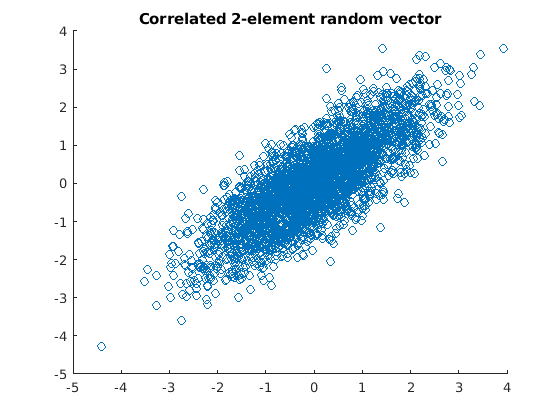


figure
scatter(x_cor(1,:), x_cor(2,:))
title('Correlated 2-element random vector')

Notice the difference between the correlated and uncorrelated random vectors. What will you change in the process if the noise you want to generate is not zero mean and with a standard deviation of 1?